**Group Codename:** Flash

**Group Members:** Nathan Devera, Carl Chua, & Michael Obciana

**Subject:** LBYEC4A

**Project Title:** Recreating an Automatic Number Plate Recognition System (ANPR) through MATLAB

Clear and Close:

clc
clear all
close all

Loading Image:

pic = imread('Plate_Number_Sample_2.PNG');
imshow(pic);
INFO = imfinfo('Plate_Number_Sample_2.PNG')

INFO = struct with fields:
                  Filename: 'D:\Z_OCR_Method\Plate_Number_Sample_2.PNG'
               FileModDate: '10-Apr-2023 20:40:13'
                  FileSize: 9721
                    Format: 'png'
             FormatVersion: []
                     Width: 324
                    Height: 87
                  BitDepth: 24
                 ColorType: 'truecolor'
           FormatSignature: [137 80 78 71 13 10 26 10]
                  Colormap: []
                 Histogram: []
             InterlaceType: 'none'
              Transparency: 'none'
    SimpleTransparencyData: []
           BackgroundColor: []
           RenderingIntent: 'perceptual'
            Chromaticities: [0.3127 0.3290 0.6400 0.3300 0.3000 0.6000 0.1500 0.0600]
                     Gamma: 0.4546
               XResolution: 4724
               YResolution: 4724
            ResolutionUnit: 'meter'
                   XOffset: []
                   YOffset: []
                OffsetUnit: []
           S

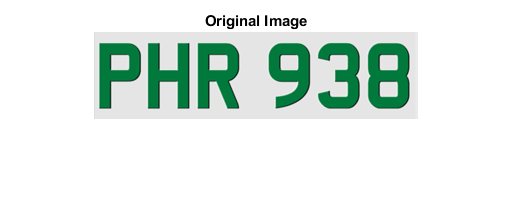

title('Original Image');

Changing the Original Image Color to Morphological:

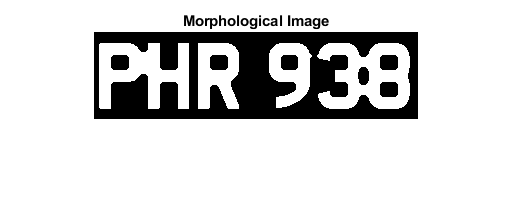

figure;
pic_gray = rgb2gray(pic);
pic_binary = imbinarize(pic_gray);
pic_flipBW = ~pic_binary;
g = strel('disk',5);
bw = imclose(pic_flipBW,g);
imshow(bw);
title('Morphological Image');

Scanning and Displaying the Text Founded in the Plate Number:

translation = ocr(bw,'TextLayout','Line','characterSet', ...
    'ABCDEFGHIJKLMNOPQRSTUVWXYZ01234567890')

translation =   ocrText with properties:

                      Text: 'PHR 938↵↵'
    CharacterBoundingBoxes: [9×4 double]
      CharacterConfidences: [9×1 single]
                     Words: {2×1 cell}
         WordBoundingBoxes: [2×4 double]
           WordConfidences: [2×1 single]


str_ocr = translation.Text;
str_ocr_no_space = strrep(str_ocr,' ', '');    % Remove Spaces
str_ocr_trim = strtrim(str_ocr_no_space);      % Remove New Line (Enter)

Detecting Last Digit:

Plate_Number = str_ocr_trim                    % Obtaining the string.

Plate_Number = 'PHR938'

Last_Digit=Plate_Number(end)                   % Get the last digit.

Last_Digit = '8'

                                               % 4 = position of a character
                                               % in a string.

Does the Plate Number Follow the 20% Number Coding Scheme?

(Assuming that the picture is taken today ).

t = datetime;
DAY = day(t,'name')

DAY = 1×1 cell array
    {'Monday'}



strMo = 'Monday';
strTu = 'Tuesday';
strWe = 'Wednesday';
strTh = 'Thursday';
strFr = 'Friday';
strSa = 'Saturday';
StrSu = 'Sunday';

LD = Last_Digit;

if contains(strMo,DAY) || contains(strWe,DAY)
    if contains(LD,'1') || contains(LD,'2')
        violation_MW = 'Has VIOLATED the Number Coding Rule'
    else
        followed_MW = 'Has followed the Number Coding Rule'
    end
elseif contains(strMo,DAY)||contains(strTh,DAY)
    if contains(LD,'3') || contains(LD,'4')
        violation_MTh = 'Has VIOLATED the Number Coding Rile'
    else 
        followed_MTh = 'Has followed the Number Coding Rule'
    end
elseif contains(strTu,DAY) || contains(strTh,DAY)
    if contains(LD,'5') || contains(LD,'6')
        violation_TuTh = 'Has VIOLATED the Number Coding Rule'
    else
        followed_Tuth = 'Has followed the Number Coding Rule'
    end
elseif contains(strTu,DAY) || contains(strFr,DAY)
    if contains(LD,'7') || contains(LD,'8')
        violation_TuFr = 'Has Violated the Number Coding Rule'
    else
        followed_TuFr = 'Has followed the Number Coding Rule'
    end
elseif contains (strWe,DAY) || contains (strFr,DAY)
    if contains(LD,'9') || contains(LD,'0')
        violation_WeFr = 'Has violated the Number Coding Rule'
    else
        followed_WeFr = 'Has followed the Number Coding Rule'
    end
end                 

followed_MW = 'Has followed the Number Coding Rule'